cd('/Volumes/PcSSDA/AChMut/20220422_112_AChmtut_SW_001')
ExperimentName='20220422_112_AChmtut_SW_001'; % Give a specific name to this experiment or this analysis
FirstAcq=13; % What's the acquisition number of the first offical recording
number_of_acq = 23; % How many chunks of recordings are there?
Dark_hours=[13 14 15 16 17 18 19 20 21 22 23 24 25]

Dark_hours =     13    14    15    16    17    18    19    20    21    22    23    24    25


darktime_calc = 0; % 0 or 1, determining different method to calculate dark time
animal='112 AChmut 1 ';

analysis_name=[ExperimentName,'_analysis_'];
timebin=1;
ch=1;
FLPfiles='continuous aquistion data_'; 

load('FLP_analysis.mat')

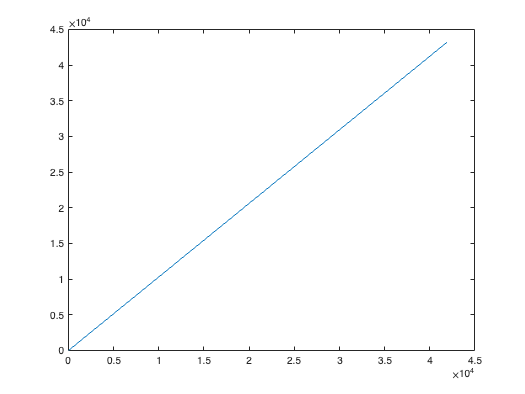

figure
plot(time_z_all_darkonly)

time_max = max(time_z_all_darkonly)

time_max = 4.3199e+04

length(time_z_all_darkonly)

ans = 41893

time_pooled = 2:4:(ceil(time_max/4)*4);
% time_pooled = zeros(ceil(time_max/4),1);
tau_pooled = zeros(ceil(time_max/4),1);
states_pooled = zeros(ceil(time_max/4),1);

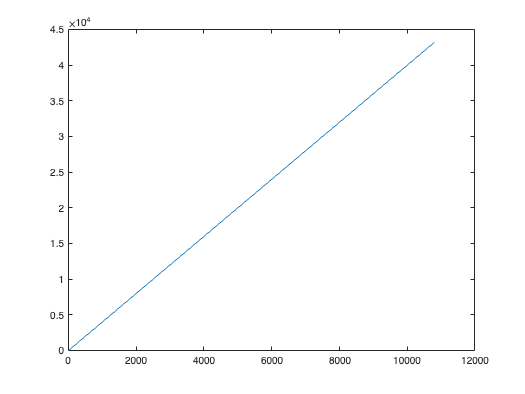

figure
plot(time_pooled)


for i = 1:ceil(time_max/4)
    index = find(time_z_all_darkonly > (i-1)*4 & time_z_all_darkonly <= i*4);

    if isempty(index) == 0
        weighted_sum = sum(tau_empTrunc_all_darkonly(index).*intensity_all_darkonly (index));
        tau_pooled(i) = weighted_sum/sum(intensity_all_darkonly (index));
        states_pooled(i) = states_for_time_all_dark(index(1));
%         time_pooled(i) = time_z_all_darkonly(index(end));
    else
        tau_pooled(i) = NaN;
        states_pooled(i) = NaN;
%         time_pooled(i) = NaN;

    end

    

end

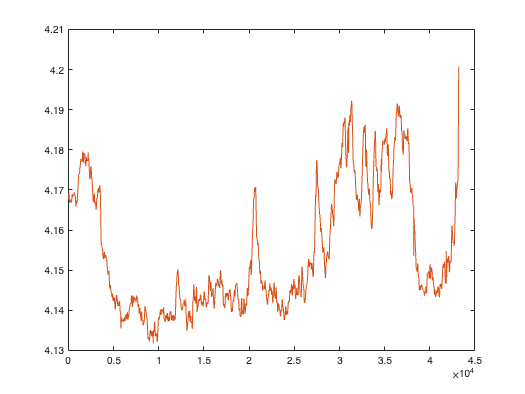

figure
plot(time_pooled, tau_pooled)
hold on
plot(time_z_all_darkonly, tau_empTrunc_all_darkonly)

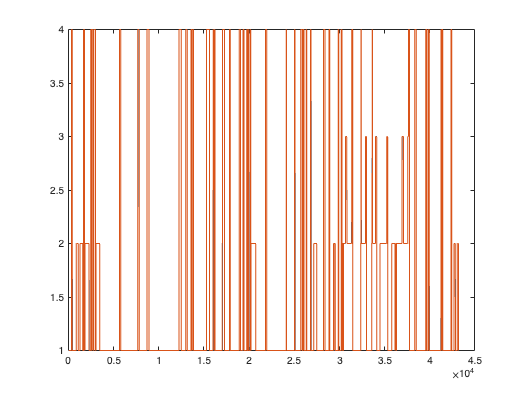

figure
plot(time_pooled, states_pooled)
hold on
plot(time_z_all_darkonly, states_for_time_all_dark)

states_added = zeros(length(states_pooled), 1) + 1;
tau_added = zeros(length(states_pooled), 1) + mean(tau_pooled, 'omitnan');

states = [states_added;states_pooled;states_added;states_pooled;states_added;states_pooled;states_added;states_pooled];
tau = [tau_added;tau_pooled;tau_added;tau_pooled;tau_added;tau_pooled;tau_added;tau_pooled];

states(find(states==2))=0;
states(find(states==3))=1;
states(find(states==4))=1;

length(states)

ans = 86400

length(tau)

ans = 86400

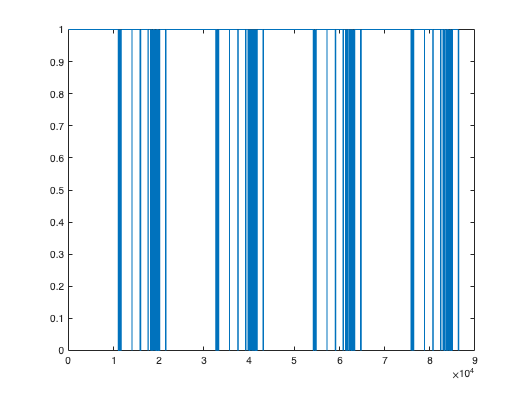

figure
plot(states)

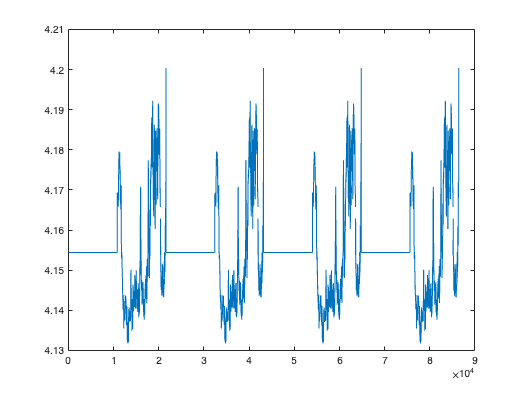

figure
plot(tau)

Temperature_path='/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/'

Temperature_path = '/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/'

cd(Temperature_path)

rawData = ([Temperature_path,ExperimentName,'_0919.mat'])

rawData = '/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/20220422_112_AChmtut_SW_001_0919.mat'

OptResults=([Temperature_path,ExperimentName,'OptResults_0919.mat'])

OptResults = '/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/20220422_112_AChmtut_SW_001OptResults_0919.mat'

save(rawData, 'time_pooled','states','tau')

edit example2_Optimization

c=parcluster

c = 

 Local Cluster

    Properties: 

                   Profile: local
                  Modified: false
                      Host: pingchuans-mbp
                NumWorkers: 21
                NumThreads: 1

        JobStorageLocation: /Users/pingchuanma/Library/Application Support/MathWorks/MATLAB/local_cluster_jobs/R2022a
   RequiresOnlineLicensing: false

    

j=batch(@example2_Optimization,1,{rawData, OptResults})

j = 

 Job

    Properties: 

                   ID: 50
                 Type: independent
             Username: pingchuanma
                State: running
       SubmitDateTime: 19-Sep-2022 16:16:06
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 